tracks_matrix = h5read('mouse4.analysis.h5','/tracks');
% frames x nodes x 2 x tracks

% identify 1 main track
nose_tracks = squeeze(tracks_matrix(:,1,1,:));
sum_nan = sum(isnan(nose_tracks),1);
% find smallest 1
[~,c] = sort(sum_nan);
main_track_id = c(1);
main_tracks = tracks_matrix(:,:,:,main_track_id);
other_tracks = tracks_matrix(:,:,:,setdiff(1:size(tracks_matrix,4), main_track_id));

new_track = [];
frame_need_attention = [];
for i = 1:size(main_tracks,1);
    temp_main = main_tracks(i,:,:,:);
    temp_main = reshape(temp_main, 1,[]);
    temp_other = reshape(other_tracks(i,:,:,:),1,[]);
    nanID = find(isnan(temp_main));
    if ~isempty(nanID)
        % first try get the info from other tracks
        other_track = reshape(other_tracks(i,:,:,:),1,[]);
        if any(~isnan(other_track))
           otherID = find(~isnan(other_track));
           idx = unique(ceil(otherID/4));
           idx = idx(1);
           main_track = other_track((idx-1)*4+1:idx*4);
        else
           temp_main(nanID) = new_track(end,nanID);
        end
    end
    new_track = [new_track; temp_main];
%     temp(isnan(temp)) = [];
%     if length(temp) >= 8
%         new_track = [new_track;temp(1:8)];
%     else
%         temp = [temp,repmat(NaN,1,8-length(temp))];
%         new_track = [new_track;temp];
%         frame_need_attention = [frame_need_attention;i];
%     end
end

## center

track_center = [1/2*(new_track(:,1)+new_track(:,2)),1/2*(new_track(:,3)+new_track(:,4))];

## remove nans

## Quadrants

qcenter = [232,214]; % [xcenter, ycenter]
qcode = [track_center(:,1)<=qcenter(1), track_center(:,2) > qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;

## visualize

vid = VideoReader('behav_video_crop.avi');
Arena = zeros(vid.Height,vid.Width,'uint8');
f = figure;
a = axes('Parent',f,'NextPlot','add');
are = imshow(Arena,'Parent',a);
a1 = line(a,new_track(1,[1,2]),new_track(1,[3,4]),'Color','white');
c = plot(a, track_center(1,1),track_center(1,2),'Marker','*');
M1q = plot(224,178,'Marker','o');
% viw = VideoWriter('track.avi','MPEG-4');
% viw.FrameRate = 30;
% open(viw);
for i = 1:size(qseries,1);
    cur_ = new_track(i,:);
    set(a1,'XData', cur_([1,2]), 'YData', cur_([3,4]));
    set(c,'XData',track_center(i,1),'YData',track_center(i,2));
    set(are, 'CData', readFrame(vid))
    switch qseries(i,1)
        case 1
            set(M1q,'XData',qcenter(1)+20,'YData',qcenter(2)-20);
        case 2
            set(M1q,'XData',qcenter(1)+20,'YData',qcenter(2)+20);
        case 3
            set(M1q,'XData',qcenter(1)-20,'YData',qcenter(2)+20);
        case 4
            set(M1q,'XData',qcenter(1)-20,'YData',qcenter(2)-20);
    end
%     s = getframe(a);
%     writeVideo(viw, s.cdata);
    drawnow;
%     pause(0.01);
end
% close(viw);
% delete(viw);

% save tracking data
save('track.mat','track_center','qcenter','qseries','new_track');

## Because didnot track individual animal, can only calculate total time spent

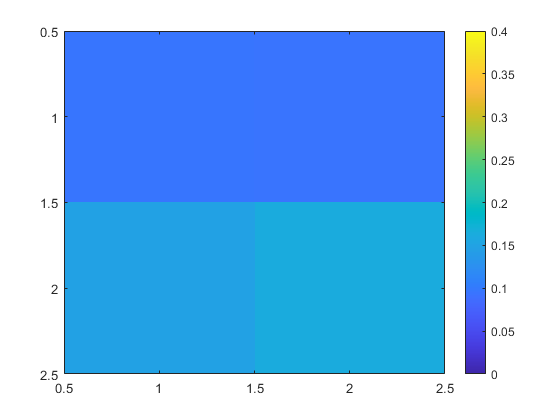

m_quadrant_perc = zeros(2,2);
m_quadrant_perc(1,2) = sum(qseries(:)==1);
m_quadrant_perc(2,2) = sum(qseries(:)==2);
m_quadrant_perc(2,1) = sum(qseries(:)==3);
m_quadrant_perc(1,1) = sum(qseries(:)==4);
m_quadrant_perc = m_quadrant_perc/(2*size(qseries,1));
figure, imagesc(m_quadrant_perc,[0,0.4]),colorbar;

## 2 individual track as control

 track2 = load('D:\Xingjian\Behavior\Quadrant_free\2021_04_26\325920-2\11_40_16\BehavCam_0\track.mat');
 track1 = load('D:\Xingjian\Behavior\Quadrant_free\2021_04_26\325920-1\11_55_48\BehavCam_0\track.mat');
 qseries1 = track1.qseries;
 qseries2 = track2.qseries;
 mlen = min(length(qseries1), length(qseries2));
 t_dist = [];
for i = 1:2000
    temp_q = circshift(qseries2, randi(round(1/4*size(qseries2,1)),1));
    qseries_new = [qseries1(1:mlen,:), temp_q(1:mlen)];
    q_diff = diff(qseries_new,[],2);
    p_time_spent_together = sum(q_diff == 0)/length(q_diff);
    p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff);
    p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff);
    t_dist = [t_dist;p_time_spent_together, p_time_spent_neighbor, p_time_spent_diag];
end
mt_dist = mean(t_dist,1)

mt_dist =     0.3132    0.4816    0.2052


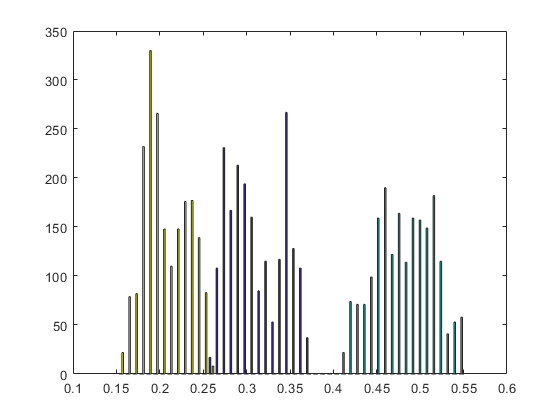

figure,hist(t_dist,50),xlim([0.1,0.6])

track12 = load('D:\Xingjian\Behavior\Quadrant_free\2021_04_26\325920-1-2\12_09_08\BehavCam_0\track.mat');
qseries12 = track12.qseries;
t_dist = [];
for i = 1:2000
    qseries_new = [qseries12(:,1), circshift(qseries12(:,2), randi(round(1/4*size(qseries,1)),1))];
    q_diff = diff(qseries_new,[],2);
    p_time_spent_together = sum(q_diff == 0)/length(q_diff);
    p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff);
    p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff);
    t_dist = [t_dist;p_time_spent_together, p_time_spent_neighbor, p_time_spent_diag];
end
mt_dist = mean(t_dist,1)

mt_dist =     0.2873    0.4939    0.2188


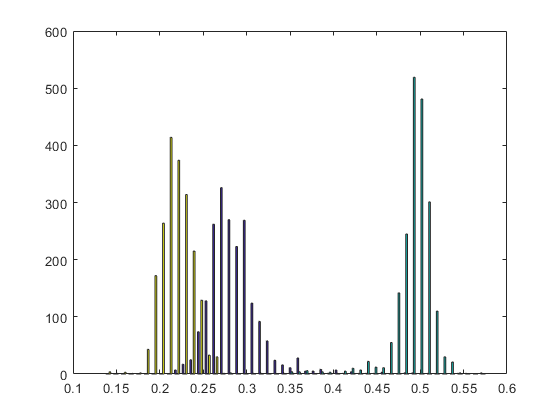

figure, hist(t_dist,50), xlim([0.1,0.6])